# EE3032-4 Quiz 6 Solution, Fall, 2019

Recall that the convolution integral is $y(t)=\int_{-\infty}^\infty x(\tau)h(t-\tau)d\tau$

Recall that the transfer function can be found by $H(\omega)=\int_{-\infty}^\infty h(t)e^{-j\omega t}dt$

## Problem 1. 

Given H(ω) = 1/(300+2jω), calculate H for a 100 Hz sinusoidal input.

f = 100; % Hz
w = 2*pi*f % radians/s

w = 628.3185

H = 1/(300+2*1j*w)

H = 1.7973e-04 - 7.5287e-04i

fprintf('H = %g at angle %g radians or %g°', abs(H), angle(H), 180/pi*angle(H))

H = 0.000774023 at angle -1.33645 radians or -76.573°

## Problem 2

Let the system input x(t) = 50 sin(2π×100t + 30°). Calculate the (steady-state, sinusoidal) output using transfer function theory.

X = 50 * exp(1j*30/180*pi); % phasor relative to sine
Y = X * H

Y = 0.0266 - 0.0281i

fprintf('y(t) = %g sin (2π × 100t + %g°); or %g radians', abs(Y), angle(Y)*180/pi, angle(Y))

y(t) = 0.0387012 sin (2π × 100t + -46.573°); or -0.812851 radians

## Problem 3

Now, consider a new system, where h(t) = u(t+2) + δ(t) – u(t-2). Sketch h(t).

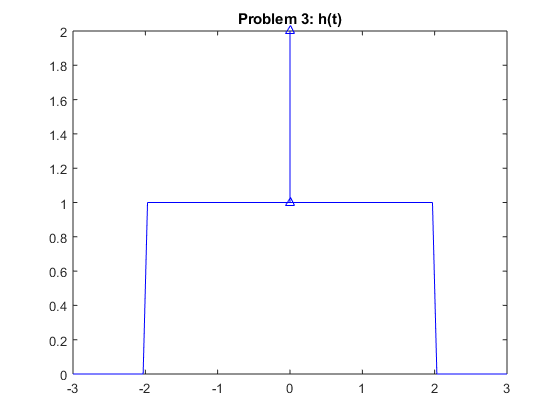

t = linspace(-3,3);
h = (t>-2) - (t>2); % not including impulse
plot(t,h,'b-', [0 0],[1 2],'b-^') % ugly way to show impulse, but it mostly works
title('Problem 3: h(t)')

## Problem 4

Calculate H(ω) for this system.

$H(\omega)=\int_{-2}^2e^{-j\omega t}dt+\int\delta(t)dt$ = $\frac{-1}{j\omega}e^{-j\omega t} |_{-2}^2+1$ = $4\frac{e^{2j\omega}-e^{-2j\omega}}{2j\times2\omega}+1$ = $4\frac{sin(2\omega)}{2\omega}+1 = 4sinc(2\omega)+1$

Note, sinc(x) = sin(x)/x is the standard mathematical definition. Using a limit approach, the discontinuity is resolved as sinc(0) = 1. This can also be shown using the Taylor series for the sine. MATLAB defines sinc(x) as sin(πx)/(πx), which is more useful in some digital signal processing and other applications, so care must be taken when using the built in version.

## Problem 5

Consider h(t) and explain why the system is BIBO stable.

h(t) is absolutely integrable. The area due to u(t+2)-u(t-2) is integral of 1 from -2 to 2, or 4. The area due to δ(t) is 1. The total area is 5, which is finite, meeting the definition.

## Problem 6

Calculate the specific value H(ω) for a 100 Hz input. Recall that, in general, H(ω) is a complex number. What is the ***angle*** of this particular result and what does that tell you about the input/output relationship?

f = 100; % Hz
w = 2*pi*f % radians/s

w = 628.3185

H = 4*sin(2*w)/(2*w)+1

H = 1

Note that H=1 when sin(2ω) = 0, which happens when ω = k π / 2. Or, when f = ω/(2π) = k / 4. Thus, for any frequency that is a multiple of 1/4 = 0.25 Hz, H=1. Note that the 0.25 Hz frequency corresponds to the 4 s time support of h(t). Since H is real, its angle is 0 and there is no phase shift. |H| = 1 means the amplitude of the input is unchanged.

In this case, H is always real, although its magnitude varies with ω.

With the exception the trivial h(t) = A δ(t), H is unconditionally real only for non-causal h(t) functions, specifically when h(t) has even symmetry.

If angle were, say, +0.2 radians, the +0.2 would be a phase shift (to the left, time advance) in the result.